  clear 


x_moto = [5,3,9]

x_moto =      5     3     9


%x_moto = randi([0,100000],1,13000);
N=length(x_moto);

K = fix(log2(N))+1

K = 2

L = 2.^[0:K-1]

L =      1     2



x= zeros(1,2*N);
x(1:N)=x_moto;

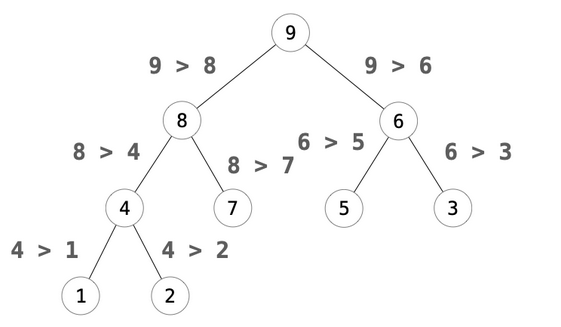

2分岐の作成


x

x =      5     3     9     0     0     0



NL=length(L);

for u=0:0% N-1
%u
        for l=flip(2:NL) % 階層レベル 下の階層から処理する。
            l
           for k=0:L(l-1)-1
               k
             m=2*k; % m,n:2分岐の右左, k:階層のどの位置か
             n=m+1;

                tmpL = x(L(l)+m);
                if tmpL < x(L(l)+n) % 左が大きいにする。
                    x(L(l)+m) = x(L(l)+n);
                    x(L(l)+n) = tmpL;
                end
            
                tmpL = x(L(l-1)+k); 
                if tmpL < x(L(l)+m) % 上が大きいにする。
                    x(L(l-1)+k) = x(L(l)+m);
                    x(L(l)+m) = tmpL;
                end
            end
        end
%x
 x_result(u+1) = x(1);
 %x(1) = -1;


end

l = 2

k = 0



x_result

x_result = 9



plot(diff(x_result(1:N)),'.')

Index exceeds the number of array elements. Index must not exceed 1.